# Questão 3

## a)

s = tf('s')

s =
 
  s
 
Continuous-time transfer function.
Model Properties


Gp = 0.2/(2*(s+0.2))

Gp =
 
     0.2
  ---------
  2 s + 0.4
 
Continuous-time transfer function.
Model Properties



zpk(Gp)

ans =
 
    0.1
  -------
  (s+0.2)
 
Continuous-time zero/pole/gain model.
Model Properties



T = 1;

Gpz = c2d(Gp, T, 'zoh');
zpk(Gpz)

ans =
 
   0.090635
  ----------
  (z-0.8187)
 
Sample time: 1 seconds
Discrete-time zero/pole/gain model.
Model Properties


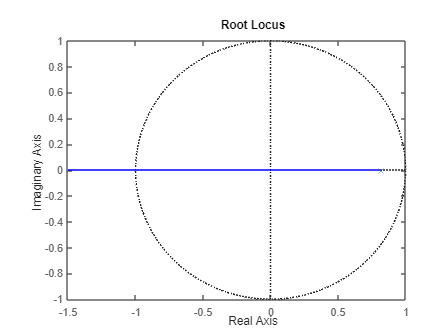


rlocus(Gpz);

## b)

Gp = 5/(s*(s+0.3))

Gp =
 
       5
  -----------
  s^2 + 0.3 s
 
Continuous-time transfer function.
Model Properties


zpk(Gp)

ans =
 
      5
  ---------
  s (s+0.3)
 
Continuous-time zero/pole/gain model.
Model Properties



T = 1;

Gpz = c2d(Gp, T, 'zoh')

Gpz =
 
     2.268 z + 2.052
  ----------------------
  z^2 - 1.741 z + 0.7408
 
Sample time: 1 seconds
Discrete-time transfer function.
Model Properties


zpk(Gpz)

ans =
 
  2.2677 (z+0.9049)
  -----------------
  (z-1) (z-0.7408)
 
Sample time: 1 seconds
Discrete-time zero/pole/gain model.
Model Properties


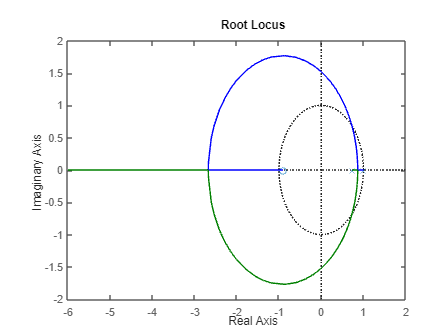


rlocus(Gpz);

## C)

Gp = 10/(s*(s+1)*(s+3))

Gp =
 
         10
  -----------------
  s^3 + 4 s^2 + 3 s
 
Continuous-time transfer function.
Model Properties



zpk(Gp)

ans =
 
       10
  -------------
  s (s+3) (s+1)
 
Continuous-time zero/pole/gain model.
Model Properties



T = 0.8;

Gpz = c2d(Gp, T, 'zoh')

Gpz =
 
    0.4185 z^2 + 0.8309 z + 0.0859
  -----------------------------------
  z^3 - 1.54 z^2 + 0.5808 z - 0.04076
 
Sample time: 0.8 seconds
Discrete-time transfer function.
Model Properties


zpk(Gpz)

ans =
 
  0.41847 (z+1.876) (z+0.1094)
  ----------------------------
  (z-1) (z-0.4493) (z-0.09072)
 
Sample time: 0.8 seconds
Discrete-time zero/pole/gain model.
Model Properties


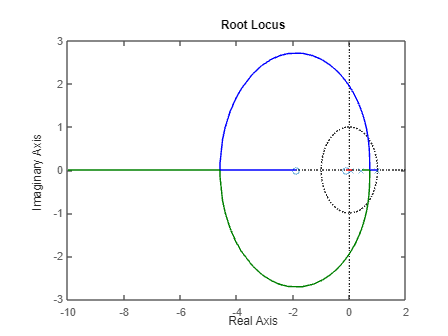


rlocus(Gpz);

## d)

Gp = 1/(s*(s+0.4)*(s+5)*(s+10))

Gp =
 
                1
  ------------------------------
  s^4 + 15.4 s^3 + 56 s^2 + 20 s
 
Continuous-time transfer function.
Model Properties



zpk(Gp)

ans =
 
            1
  ----------------------
  s (s+10) (s+5) (s+0.4)
 
Continuous-time zero/pole/gain model.
Model Properties



T = 1;

Gpz = c2d(Gp, T, 'zoh')

Gpz =
 
  0.004859 z^3 + 0.01059 z^2 + 0.0009269 z + 8.924e-07
  -----------------------------------------------------
  z^4 - 1.677 z^3 + 0.6817 z^2 - 0.004548 z + 2.051e-07
 
Sample time: 1 seconds
Discrete-time transfer function.
Model Properties


zpk(Gpz)

ans =
 
  0.0048592 (z+2.087) (z+0.09038) (z+0.0009736)
  ---------------------------------------------
   (z-1) (z-0.6703) (z-0.006738) (z-4.54e-05)
 
Sample time: 1 seconds
Discrete-time zero/pole/gain model.
Model Properties


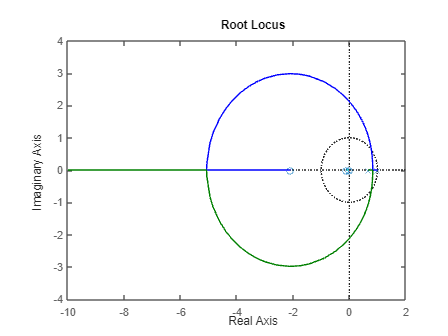


rlocus(Gpz);

# Questão 4

Gp = 20*10^3/(s*(s+100))

Gp =
 
     20000
  -----------
  s^2 + 100 s
 
Continuous-time transfer function.
Model Properties



zpk(Gp)

ans =
 
    20000
  ---------
  s (s+100)
 
Continuous-time zero/pole/gain model.
Model Properties



T = 0.01;

Gpz = c2d(Gp, T, 'zoh')

Gpz =
 
    0.7358 z + 0.5285
  ----------------------
  z^2 - 1.368 z + 0.3679
 
Sample time: 0.01 seconds
Discrete-time transfer function.
Model Properties


Gpz_zpk = zpk(Gpz)

Gpz_zpk =
 
  0.73576 (z+0.7183)
  ------------------
   (z-1) (z-0.3679)
 
Sample time: 0.01 seconds
Discrete-time zero/pole/gain model.
Model Properties


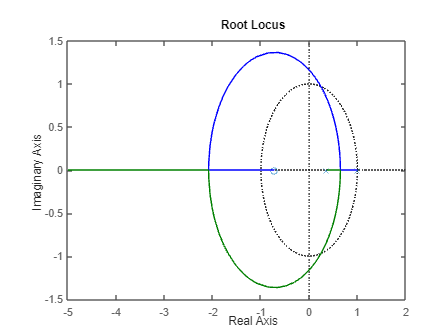


rlocus(Gpz);


Tz = feedback(Gpz * 0.2, 1);
Tz_zpk = zpk(Tz)

Tz_zpk =
 
    0.14715 (z+0.7183)
  -----------------------
  (z^2 - 1.221z + 0.4736)
 
Sample time: 0.01 seconds
Discrete-time zero/pole/gain model.
Model Properties


pole(Tz)

ans =    0.6104 + 0.3179i
   0.6104 - 0.3179i


zero(Tz)

ans = -0.7183

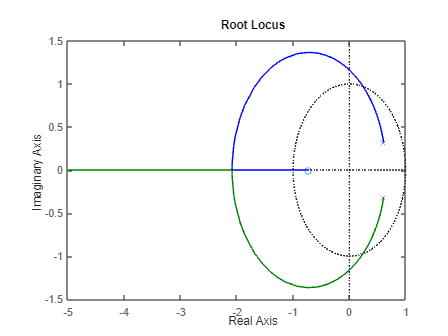


rlocus(Tz)

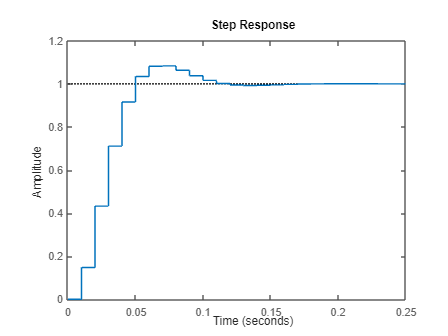

step(Tz)

# Quesão 15

Gp = 1/(s+2)

Gp =
 
    1
  -----
  s + 2
 
Continuous-time transfer function.
Model Properties



zpk(Gp)

ans =
 
    1
  -----
  (s+2)
 
Continuous-time zero/pole/gain model.
Model Properties



T = 0.5;

Gpz = c2d(Gp, T, 'zoh')

Gpz =
 
    0.3161
  ----------
  z - 0.3679
 
Sample time: 0.5 seconds
Discrete-time transfer function.
Model Properties


zpk(Gpz)

ans =
 
   0.31606
  ----------
  (z-0.3679)
 
Sample time: 0.5 seconds
Discrete-time zero/pole/gain model.
Model Properties


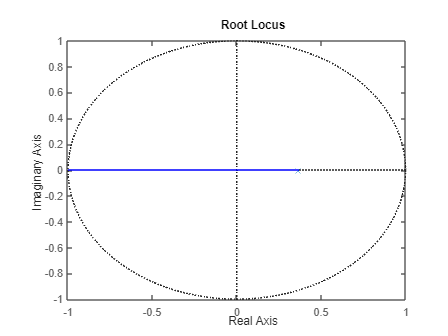


rlocus(Gpz);

# Questão 17 - Nise

Gp = 1/((s+1)*(s+4))

Gp =
 
        1
  -------------
  s^2 + 5 s + 4
 
Continuous-time transfer function.
Model Properties



zpk(Gp)

ans =
 
       1
  -----------
  (s+4) (s+1)
 
Continuous-time zero/pole/gain model.
Model Properties



T = 0.1;

Gpz = c2d(Gp, T, 'zoh')

Gpz =
 
  0.004248 z + 0.003596
  ----------------------
  z^2 - 1.575 z + 0.6065
 
Sample time: 0.1 seconds
Discrete-time transfer function.
Model Properties


zpk(Gpz)

ans =
 
  0.0042475 (z+0.8466)
  ---------------------
  (z-0.9048) (z-0.6703)
 
Sample time: 0.1 seconds
Discrete-time zero/pole/gain model.
Model Properties


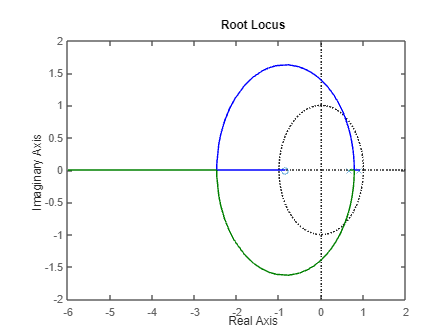


rlocus(Gpz);

# Questão 13.5 chen

1. Malha aberta

Gp = 1/(s*(s+2));
zpk(Gp)

ans =
 
     1
  -------
  s (s+2)
 
Continuous-time zero/pole/gain model.
Model Properties


T = 1;

Gpz = c2d(Gp, T, 'zoh');

zpk(Gpz)

ans =
 
  0.28383 (z+0.5232)
  ------------------
   (z-1) (z-0.1353)
 
Sample time: 1 seconds
Discrete-time zero/pole/gain model.
Model Properties


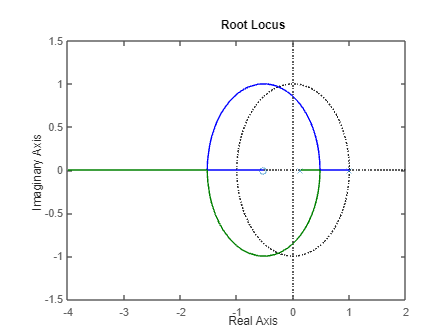

rlocus(Gpz);

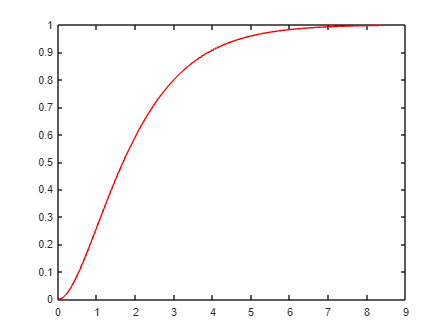


[y, tOut] = step(feedback(Gp, 1));
plot(tOut, y, color='red');

2. Controlador

z = tf('z');

K = 0.4876

K = 0.4876

Gcz = (K*(z+0.25))/(z-0.156);
zpk(Gcz)

ans =
 
  0.4876 (z+0.25)
  ---------------
     (z-0.156)
 
Sample time: unspecified
Discrete-time zero/pole/gain model.
Model Properties



FT_cl = feedback(Gpz * Gcz, 1);
FT_cl_zpk = zpk(FT_cl)

FT_cl_zpk =
 
       0.1384 (z+0.5232) (z+0.25)
  ------------------------------------
  (z-0.007323) (z^2 - 1.146z + 0.4111)
 
Sample time: 1 seconds
Discrete-time zero/pole/gain model.
Model Properties


pole(FT_cl_zpk)

ans =    0.5728 + 0.2880i
   0.5728 - 0.2880i
   0.0073 + 0.0000i


zero(FT_cl_zpk)

ans =    -0.5232
   -0.2500


3.Resposta ao degrau

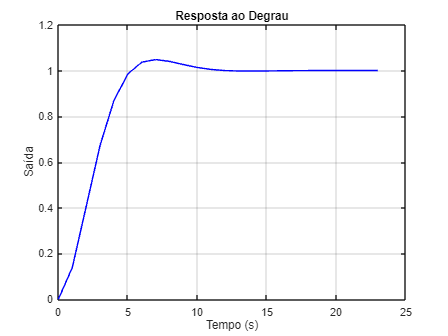

[y_cl, tOut_cl] = step(FT_cl);
plot(tOut_cl, y_cl, 'Color', 'blue');
xlabel('Tempo (s)');
ylabel('Saída');
title('Resposta ao Degrau');
grid on;


% Obtém informações da resposta ao degrau
info = stepinfo(y_cl, tOut_cl);

% Tempo de acomodação a 2%
tempo_acomodacao = info.SettlingTime;

% Ultrapassagem percentual
ultrapassagem = info.Overshoot;

% Exibe os resultados no console
fprintf('Tempo de acomodação a 2%%: %.4f s\n', tempo_acomodacao);

Tempo de acomodação a 2%: 9.4764 s


fprintf('Ultrapassagem percentual: %.2f%%\n', ultrapassagem);

Ultrapassagem percentual: 4.79%


4. Alternativa

Gp = 2.098/(s*(s+2));
zpk(Gp)

ans =
 
   2.098
  -------
  s (s+2)
 
Continuous-time zero/pole/gain model.
Model Properties


T = 1;

Gpz = c2d(Gp, T, 'zoh');

zpk(Gpz)

ans =
 
  0.59548 (z+0.5232)
  ------------------
   (z-1) (z-0.1353)
 
Sample time: 1 seconds
Discrete-time zero/pole/gain model.
Model Properties



FT_cl = feedback(Gp, 1)

FT_cl =
 
        2.098
  -----------------
  s^2 + 2 s + 2.098
 
Continuous-time transfer function.
Model Properties


FT_cl_zpk = zpk(FT_cl)

FT_cl_zpk =
 
        2.098
  ------------------
  (s^2 + 2s + 2.098)
 
Continuous-time zero/pole/gain model.
Model Properties


pole(FT_cl_zpk)

ans =   -1.0000 + 1.0479i
  -1.0000 - 1.0479i


zero(FT_cl_zpk)


ans =

  0×1 empty double column vector



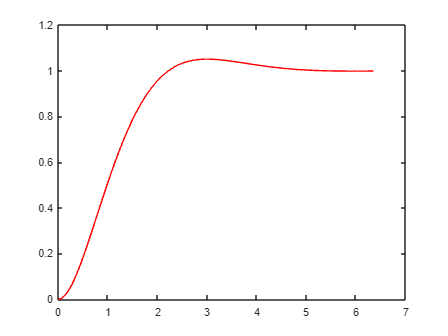


[y, tOut] = step(FT_cl);
plot(tOut, y, color='red');


info = stepinfo(y, tOut);

% Tempo de acomodação a 2%
tempo_acomodacao = info.SettlingTime;

% Ultrapassagem percentual
ultrapassagem = info.Overshoot;

% Exibe os resultados no console
fprintf('Tempo de acomodação a 2%%: %.4f s\n', tempo_acomodacao);

Tempo de acomodação a 2%: 4.2173 s


fprintf('Ultrapassagem percentual: %.2f%%\n', ultrapassagem);

Ultrapassagem percentual: 5.22%


# Questão 13.12 chen

1. Malha aberta

z = tf('z');

Gpz = (z+1)/((z-0.3)*(z-1));
zpk(Gpz)

ans =
 
      (z+1)
  -------------
  (z-1) (z-0.3)
 
Sample time: unspecified
Discrete-time zero/pole/gain model.
Model Properties


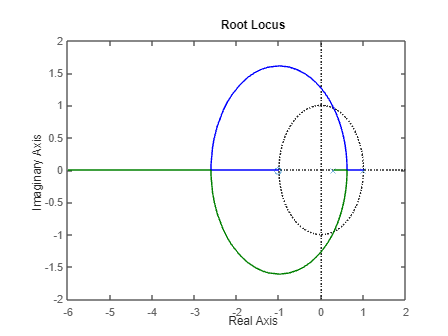

T = 1;

rlocus(Gpz);


[y, tOut] = step(feedback(Gp, 1));
plot(tOut, y, color='red');

2. Controlador

K = 0.277

K = 0.2770

Gcz = (K*(z-0.288))/(z+0.073);
zpk(Gcz)

ans =
 
  0.277 (z-0.288)
  ---------------
     (z+0.073)
 
Sample time: unspecified
Discrete-time zero/pole/gain model.
Model Properties



FT_cl = feedback(Gpz * Gcz, 1);
FT_cl_zpk = zpk(FT_cl)

FT_cl_zpk =
 
         0.277 (z+1) (z-0.288)
  -----------------------------------
  (z-0.2592) (z^2 - 0.6908z + 0.2233)
 
Sample time: unspecified
Discrete-time zero/pole/gain model.
Model Properties


pole(FT_cl_zpk)

ans =    0.3454 + 0.3224i
   0.3454 - 0.3224i
   0.2592 + 0.0000i


zero(FT_cl_zpk)

ans =    -1.0000
    0.2880


3.Resposta ao degrau

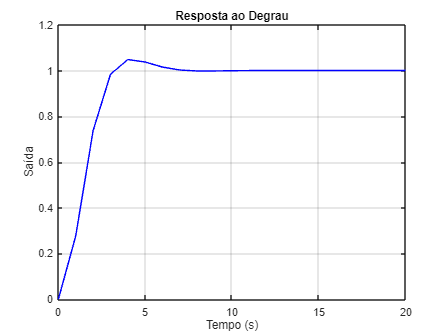

[y_cl, tOut_cl] = step(FT_cl);
plot(tOut_cl, y_cl, 'Color', 'blue');
xlabel('Tempo (s)');
ylabel('Saída');
title('Resposta ao Degrau');
grid on;


% Obtém informações da resposta ao degrau
info = stepinfo(y_cl, tOut_cl);

% Tempo de acomodação a 2%
tempo_acomodacao = info.SettlingTime;

% Ultrapassagem percentual
ultrapassagem = info.Overshoot;

% Exibe os resultados no console
fprintf('Tempo de acomodação a 2%%: %.4f s\n', tempo_acomodacao);

Tempo de acomodação a 2%: 5.7743 s


fprintf('Ultrapassagem percentual: %.2f%%\n', ultrapassagem);

Ultrapassagem percentual: 4.82%
